# Fig 6BC

Boxplots of mediolateral position of TA and LG excitatory premotor interneurons

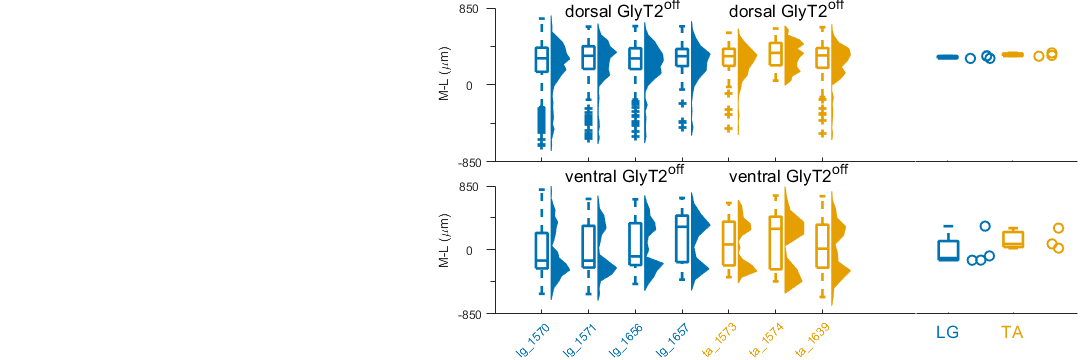

% plots correlation matrix for all experiments

masterdir = 'F:\documents\master\data\';
clearvars -except masterdir


    dn = {[masterdir,'lg_exc_chat\'],...
        [masterdir,'ta_exc_chat\']};%,...
    ndir = length(dn);
    for i = 1:ndir
        %labels{i} =  [extractBetween(dn{i},'norm\','\'),'--',dn{i}( strlength(dn{i})-2 :strlength(dn{i})-1) ]  ;
        labels{i} =  extractBetween(dn{i},'norm\','\')  ;
        labels{i} = extractBefore(labels{i},3);
    end


%%%%%%%%%%%%%%% switch to go straight to figure, rather than redoing
%%%%%%%%%%%%%%% calculations
readdata = 1;
%%%%%%%%%%%%%%%%

% figure settings
nr1 = 2;               % Number of rows in panel grid
nc1 = 3;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size



% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 0;  % if concat=1 concatenates all files in directory
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [5,5];          % kernel size
res = [20,20]; % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if readdata

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 
[allins,allmns] = poolfun(dn,1); % ins and mns have the same dimensions 


for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% color settings
% color settings
first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory or all
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory or PL
third = [0,0,1];

%allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for GS and TA
allcolor = vertcat(repmat(first,nfiles(1),1), repmat(second,nfiles(2),1)); % for other pairs of muscles

ndir = length(dn);
ext = 'xlsx';

for i = 1:ndir
files_{i} = dir([dn{i},'*.',ext]);
end
firstins = [];
for i = 1:nfiles(1)
        firstname_{i} = files_{1}(i).name;
        firstmusclename{i} = extractBefore(firstname_{i},3);
        firstmusclename{i} = strrep(firstmusclename{i},'gs','lg');
        firstfilename{i} = extractBefore(firstname_{i},'.xlsx');
        firstfilename{i} = extractAfter(firstfilename{i},6);
        firstexpname{i} = [firstmusclename{i},firstfilename{i}];
        firstname{i} = insertBefore(firstexpname{i}, 'lg','\color[rgb]{0, 0.4471, 0.6980}'); %= [0, 114, 178]/255;  %blu = 2nd directory = GS;
        firstins = vertcat(firstins,ins{1}{i});
end
secondins = [];
for i = 1:nfiles(2)
        secondname_{i} = files_{2}(i).name;
        secondmusclename{i} = extractBefore(secondname_{i},3);
        secondmusclename{i} = strrep(secondmusclename{i},'gs','lg');
        secondfilename{i} = extractBefore(secondname_{i},'.xlsx');
        secondfilename{i} = extractAfter(secondfilename{i},6);
        secondexpname{i} = [secondmusclename{i},secondfilename{i}];
        secondname{i} = insertBefore(secondexpname{i}, 'ta','\color[rgb]{0.9020, 0.6235,0}'); % =[230, 159, 0]/255; %orange = 1st directory = TA;
        secondins = vertcat(secondins,ins{2}{i});
end
names = horzcat(firstname, secondname);
names = insertBefore(names,'_','\');
firstins_d = firstins(firstins(:,2)>0,:);
firstins_v = firstins(firstins(:,2)<=0,:);
secondins_d = secondins(secondins(:,2)>0,:);
secondins_v = secondins(secondins(:,2)<=0,:);


for i = 1:ndir
    for j = 1:nfiles(i)
       median_ml_d{i}(j) = median(ins{i}{j}(ins{i}{j}(:,2)>0,1));
       median_ml_v{i}(j) = median(ins{i}{j}(ins{i}{j}(:,2)<=0,1));
    end
end

%%%%%%%%%%%%% Starts bootstrap calculations on dorsal  or ventral side only
% depending on the value of temp

% twisted code to keep directory grouping (as a cell array) and
% concatenating all dorsal ipsi coordinates into a matrix that can be read
% by bootstrap code (rows are animals, columns are coordinates, NaNs are
% all at the end)
temp = cell(1,ndir);
ins_d_ipsi = cell(1,ndir);
boot_mean = cell(1,ndir);
boot_sd = cell(1,ndir);
boot_size = cell(1,ndir);
p_boot = zeros(ndir,ndir);
boot_hedges_median = zeros(ndir,ndir);
boot_hedges = cell(1,ndir);
nruns = 5000;

for i = 1:ndir
    for j = 1:nfiles(i)
        % dorsal ipsi
%         temp{i}{j} = ins{i}{j}(ins{i}{j}(:,2)>0 & ins{i}{j}(:,1)>0 ,1); %selects x coordinates for neurons in the ipsi dorsal quaadrant
        %ventral all
        temp{i}{j} = ins{i}{j}(ins{i}{j}(:,2)<0  ,1);
    end
    ins_d_ipsi{i} = (nanhcat(temp{i}{:}))'; %animals are now rows, coordinates are column 
    %(to accomodate for hierarchicla bootstrap code by Sam Sober). Index i
    %is the muscle/experiment/directory
end
% % defines the size of bootstrap at the level of animal
% num_trials = 1*max(size(ins_d_ipsi{2},2),size(ins_d_ipsi{1},2));
% for i = 1:ndir
%     [boot_mean{i}, boot_sd{i},boot_size{i}] = get_bootstrapped_stats(ins_d_ipsi{i},nruns,num_trials,'mean');
% end
% 
% for i = 1:ndir
%     for j = 1:ndir
%         p_boot(i,j) = (get_direct_prob(boot_mean{i},boot_mean{j}));
%         hh = boot_mean{i}-boot_mean{j};
%         nx = boot_size{i}(1); %All boot  sizes are the same
%         ny = boot_size{j}(1); %All boot  sizes are the same
%         pooled_s = sqrt( ((nx-1)*boot_sd{i}.^2 + (ny-1)*boot_sd{j}.^2)/(nx+ny-2) );
%         boot_hedges{i}{j} = hh./pooled_s;
%         boot_hedges_median(i,j) = median(boot_hedges{i}{j}); 
%     end
% end

gck = gckernel();
setKernel(gck,ker);
setResd(gck,res);
junk = gck.convolve([allins{1}{1}(:,1)' ; allins{1}{1}(:,2)']); %intializes values of bins


% method 1
for i = 1:ndir
    for j = 1:nfiles(i)
        conv_result1{i}{j} = gck.convolve ([ins{i}{j}(:,1)';ins{i}{j}(:,2)']);
    end
end

% Lines up the files from the two direcotries to give a single matrix
for  i = 1:ndir
    for j = 1:nfiles(i)
        j+(i-1)*nfiles(ndir-1);
        conv_result_all{j+(i-1)*nfiles(ndir-1)} =conv_result1{i}{j};
        conv_result_ml{j+(i-1)*nfiles(ndir-1)} =sum(conv_result1{i}{j},1);
        ins_all{j+(i-1)*nfiles(ndir-1)} = ins{i}{j};
    end
end

ins_all_mat_d=[];
ins_all_mat_v=[];
for i = 1:size(ins_all,2)
    ins_all_mat_d = nanhcat(ins_all_mat_d,ins_all{i}(ins_all{i}(:,2)>0  ,1));
    ins_all_mat_v = nanhcat(ins_all_mat_v,ins_all{i}(ins_all{i}(:,2)<=0  ,1));
end

for i = 1: size(conv_result_all,2)
    for j = 1:size(conv_result_all,2)
       
     %CXYconv(i,j) = corr2(conv_result_all{i},conv_result_all{j}); % uses the mean as center of distributions
     CXYconv(i,j) = corr2median(conv_result_all{i},conv_result_all{j}); % uses the median as center of distributions
%      [HKS(i,j), pKS(i,j), KSstatistic] = kstest2(conv_result_ml{i}, conv_result_ml{j});  
%      [pperm(i,j), observeddifference, effectsize] = permutationTest(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1),1000);
     [pranksum_x(i,j), Hranksum_x(i,j),ranksumstatistic_x(i,j)] = ranksum(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1));  
    
     
    end
end

else
end

f1 = figure;
%set(f1,'Position',[1 1 f1.Position(3) f1.Position(4)])
h = 0;
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(1,[0.2,-0.82],[1.05,1.68]);
Panels.tweak(2,[0.36,0.],[1.3,0.95]);
Panels.tweak(3,[0.55,0.0],[0.5,0.95]);
Panels.tweak(5,[0.36,0.],[1.3,0.95]);
Panels.tweak(6,[0.55,0.172],[0.5,0.8]);

% correlation panel;
%hmap =heatmap(CXYHIST,'XDisplayLabels',names, 'YDisplayLabels',names, 'CellLabelColor','r');
% h =1;
% corr_fig = Panels.setPanel(h);
% %set(gcf,'Name','correlation from convolution');
% mapcorr = imagesc(CXYconv, [0,1]);
% ax = gca;
%  set (ax,'YTick',1:sum(nfiles),'YTickLabel',names,'XTick',1:sum(nfiles),'XTickLabel',...
%      names, 'XTickLabelRotation', 45);
% hold on
% cbcorr = colorbar;
% set(cbcorr,'FontSize',10, 'Ticks',[0,1] );
% cbcorr.Label.String = {'correlation'};
% cbcorr.Label.FontSize = 15;
% cbcorr.Label.Rotation = -90;
% cbcorr.Label.Position = [2.2879 0.5000 0];
% ph = plot([nfiles(1)+0.5,nfiles(1)+0.5],[1-0.5,sum(nfiles)+0.5],'k','LineWidth',3);
% plot([1-0.5,sum(nfiles)+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'k','LineWidth',3);
% colormap(gray)
% caxis([0,1]);

h =2;
allins_fig = Panels.setPanel(h);
bpall = boxplot(ins_all_mat_d,'width',0.25,'Color',allcolor, 'Symbol','+');
hold on
set(bpall,{'linew'},{2})
axall=gca;
set(axall,'XLim',[0,2*nfiles(1)+1],'YLim',[-0.5,0.5],'TickLabelInterpreter','tex',...
    'XTick',1:sum(nfiles),'XTickLabel',[], 'XTickLabelRotation', 45,...
    'YTick', [-0.5,0,0.5], 'YTickLabels',  [-850,0,850],...
    'YTickLabelRotation', 0);
set(axall.YLabel,'Interpreter','tex');
         axall.YLabel.String = 'M-L (\mum)';
         axall.YLabel.Position = [-0.95 0.08];
         axall.YAxis.FontSize = 11;
         axall.YAxis.FontName = 'arial';
         axall.YAxis.MinorTick = 'on';
         axall.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         axall.YAxis.TickDirection = 'out';
         axall.YAxis.TickLength = [0.0200 .3250];
yrule = axall.YAxis;
yrule.FontSize = 13;
text(1.5,0.5,'dorsal GlyT2^{off}','FontSize',13, 'Interpreter','tex');
text(5.,0.5,'dorsal GlyT2^{off}','FontSize',13, 'Interpreter','tex');
viol_all_d = dischart(ins_all_mat_d, (1:size(ins_all_mat_d,2))+0.2,...
    [0, 0.4],0,'r' , 'r');
for i = 1:size(viol_all_d,2)
    set(viol_all_d{i}, 'FaceColor',allcolor(i,:), 'EdgeColor',allcolor(i,:));
end
%axall.YLabel.String = 'median';
%plot([0,7.5],[0.5,0.5]);

box off


h =3;
summary_fig = Panels.setPanel(h);
bp = boxplot(nanhcat(median_ml_d{1}', median_ml_d{2}'),'Color',[first;second]);
set(bp,{'linew'},{2})
ax3 = gca;
set(ax3,'XLim',[0.5,3],'YLim',[-0.5,0.5],'XTickLabel',[],'TickLabelInterpreter','tex',...
        'FontSize',16);
ax3.YAxis.Visible = 'off';
hold on
ps = dischart(nanhcat(median_ml_d{1}', median_ml_d{2}'),[1.5,2.5],0.4,[],'','','o');
set(ps{1},'MarkerEdgeColor',first,'LineWidth',1.5, 'MarkerSize',7);
set(ps{2},'MarkerEdgeColor',second,'LineWidth',1.5, 'MarkerSize',7);
box off
%plot([0,7.5],[0.5,0.5]);

h =5;
allins_fig = Panels.setPanel(h);
bpall = boxplot(ins_all_mat_v,'width',0.25,'Color',allcolor, 'Symbol','+');
hold on
set(bpall,{'linew'},{2})
axall=gca;
set(axall,'XLim',[0,2*nfiles(1)+1],'YLim',[-0.5,0.5],'TickLabelInterpreter','tex',...
    'XTick',1:sum(nfiles),'XTickLabel',names, 'XTickLabelRotation', 45,...
    'YTick', [-0.5,0,0.5], 'YTickLabels',  [-850,0,850],...
    'YTickLabelRotation', 0);
set(axall.YLabel,'Interpreter','tex');
         axall.YLabel.String = 'M-L (\mum)';
         axall.YLabel.Position = [-0.95 0.08];
         axall.YAxis.FontSize = 11;
         axall.YAxis.FontName = 'arial';
         axall.YAxis.MinorTick = 'on';
         axall.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         axall.YAxis.TickDirection = 'out';
         axall.YAxis.TickLength = [0.0200 .3250];
yrule = axall.YAxis;
yrule.FontSize = 13;
text(1.5,0.6,'ventral GlyT2^{off}','FontSize',13, 'Interpreter','tex');
text(5.,0.6,'ventral GlyT2^{off}','FontSize',13, 'Interpreter','tex');
viol_all_v = dischart(ins_all_mat_v, (1:size(ins_all_mat_v,2))+0.2, [0, 0.4],0,'r' , 'r');
for i = 1:size(viol_all_v,2)
    set(viol_all_v{i}, 'FaceColor',allcolor(i,:), 'EdgeColor',allcolor(i,:));
end
%axall.YLabel.String = 'median';
%plot([0,7.5],[0.5,0.5]);

box off


h =6;
summary_fig = Panels.setPanel(h);
bp = boxplot(nanhcat(median_ml_v{1}', median_ml_v{2}'),'Color',[first;second]);
hold on
set(bp,{'linew'},{2})
ax5 = gca;
set(ax5,'XLim',[0.5,3],'YLim',[-0.5,0.5],'TickLabelInterpreter','tex',...
    'XTickLabel',{'\color[rgb]{0, 0.4471, 0.6980}LG', '\color[rgb]{0.9020, 0.6235,0}TA'},...
    'FontSize',13);
ax5.YAxis.Visible = 'off';
hold on
ps = dischart(nanhcat(median_ml_v{1}', median_ml_v{2}'),[1.5,2.5],0.4,[],'','','o');
set(ps{1},'MarkerEdgeColor',first,'LineWidth',1.5, 'MarkerSize',7);
set(ps{2},'MarkerEdgeColor',second,'LineWidth',1.5, 'MarkerSize',7);
%plot([0,7.5],[0.5,0.5]);
box off


Panels.addPanels();